c1=1;
c2=2;
k1=3;
k2=4;
m1=5;
m2=6;
F=7;


%transmitnce
M=[m1 0;0 m2];
C2=[c1 -c1;-c1 (c1+c2)];
K=[k1 -k2;-k1 k1+k2];

%transmittance
s = tf('s');
T = 1/(M.*s^2+C2.*s+K)

T =
 
  From input 1 to output...
              0.2 s^2 + 0.1 s + 0.2333
   1:  ---------------------------------------
       s^4 + 0.7 s^3 + 1.833 s^2 + 0.3 s + 0.3
 
                   0.03333 s + 0.1
   2:  ---------------------------------------
       s^4 + 0.7 s^3 + 1.833 s^2 + 0.3 s + 0.3
 
  From input 2 to output...
                 0.03333 s + 0.1333
   1:  ---------------------------------------
       s^4 + 0.7 s^3 + 1.833 s^2 + 0.3 s + 0.3
 
            0.1667 s^2 + 0.03333 s + 0.1
   2:  ---------------------------------------
       s^4 + 0.7 s^3 + 1.833 s^2 + 0.3 s + 0.3
 
Continuous-time transfer function.




%state
A=[c1/m1 0 k1/m1 0; c1/m1 (-c1-c2)/m2 k1/m2 (-k1-k2)/m2;
    1 0 0 0; 0 1 0 0];
B=[1/m1;0;0;0];
C=[0 0 1 0; 0 0 0 1];
D=[0];
%state space
sys = ss(A,B,C,D);
H=tf(sys)

H =
 
  From input to output...
              0.2
   1:  -----------------
       s^2 - 0.2 s - 0.6
 
                      0.04 s + 0.1
   2:  -------------------------------------------
       s^4 + 0.3 s^3 + 0.4667 s^2 - 0.5333 s - 0.7
 
Continuous-time transfer function.



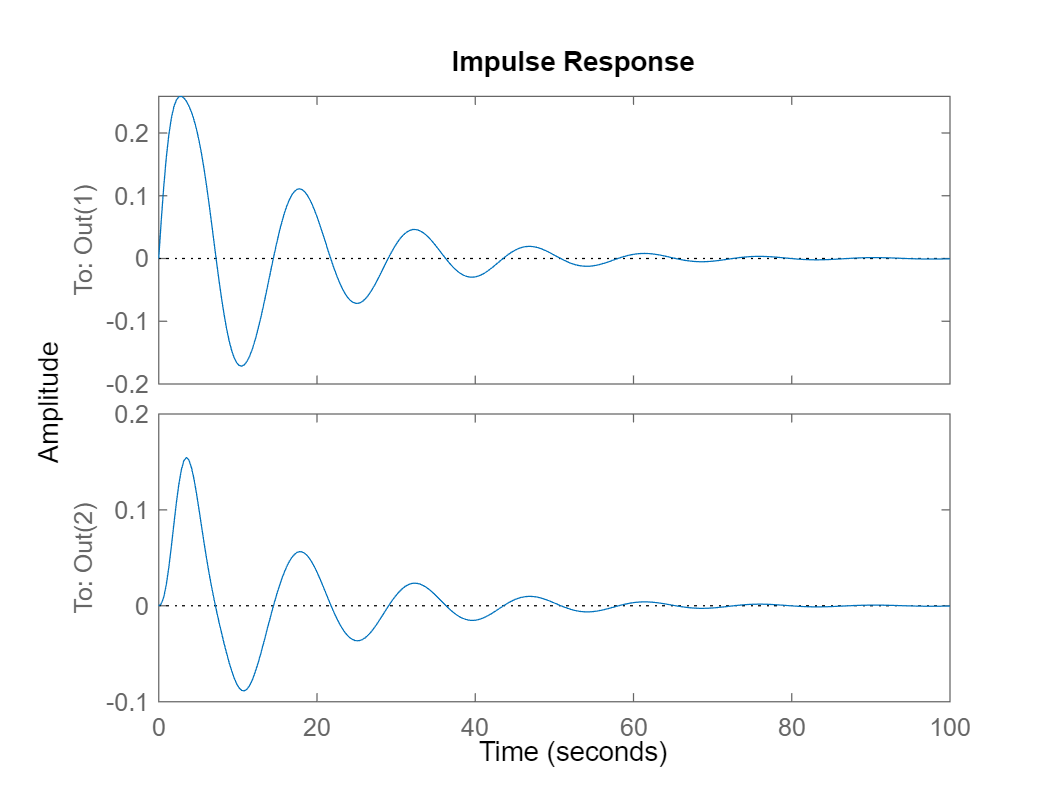

figure(1)
impulse(T(:,1))

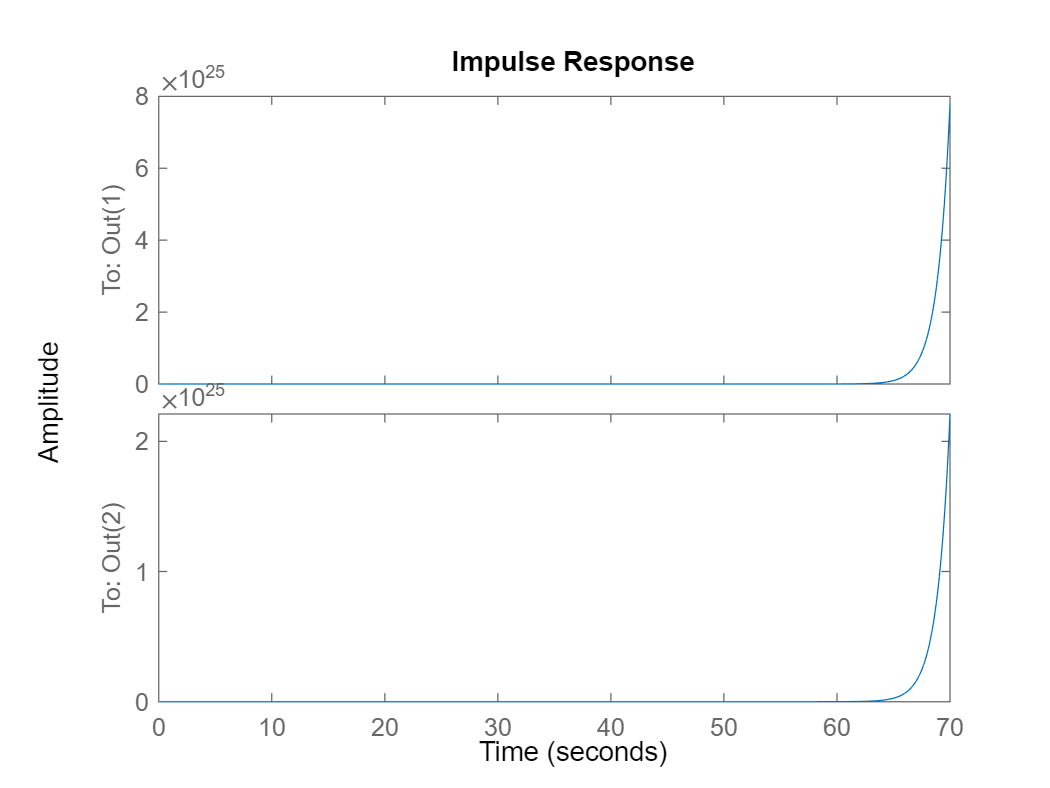

figure(2)
impulse(H)

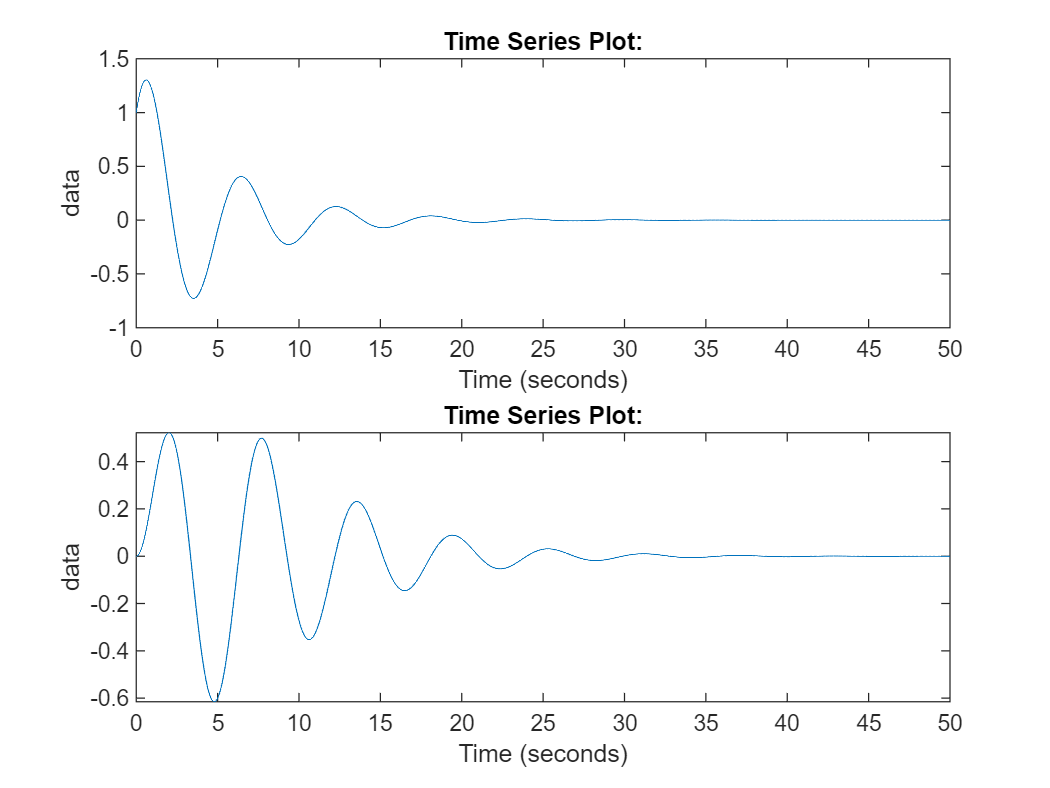

out=sim("reportsim.slx");

figure(3)
subplot(2,1,1)
plot(out.impulse1);
subplot(2,1,2)
plot(out.impulse2);

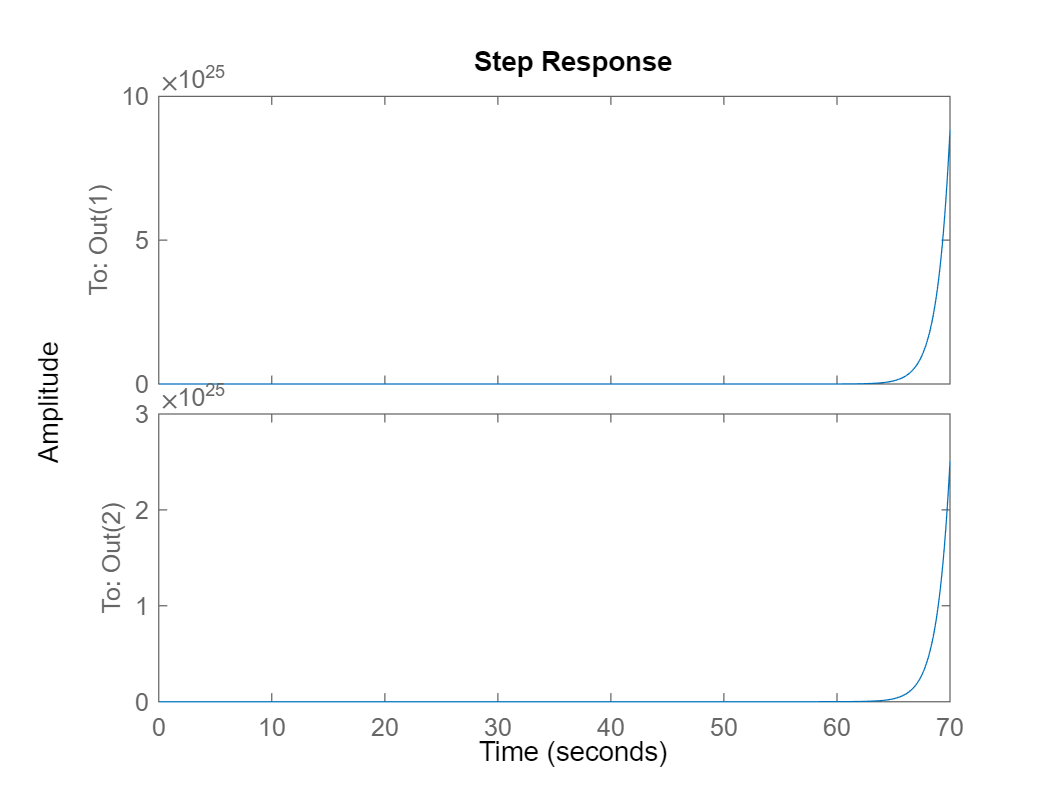

figure(4)
step(H(:,1))

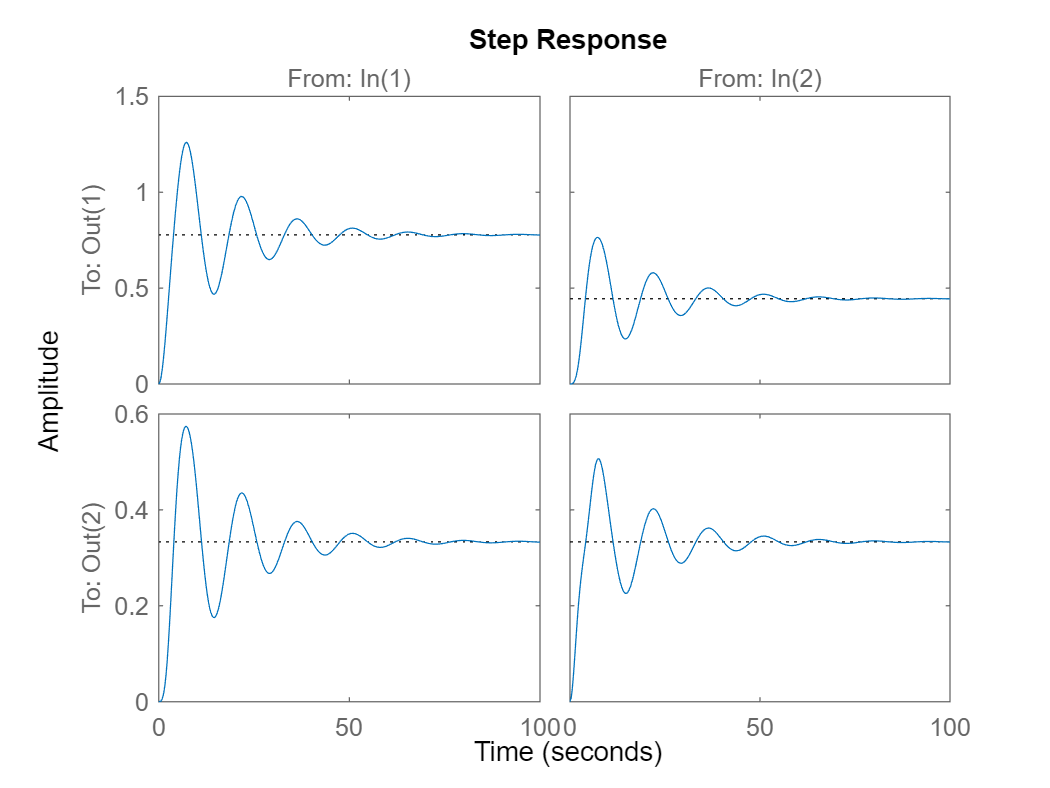

figure(5)
step(T)

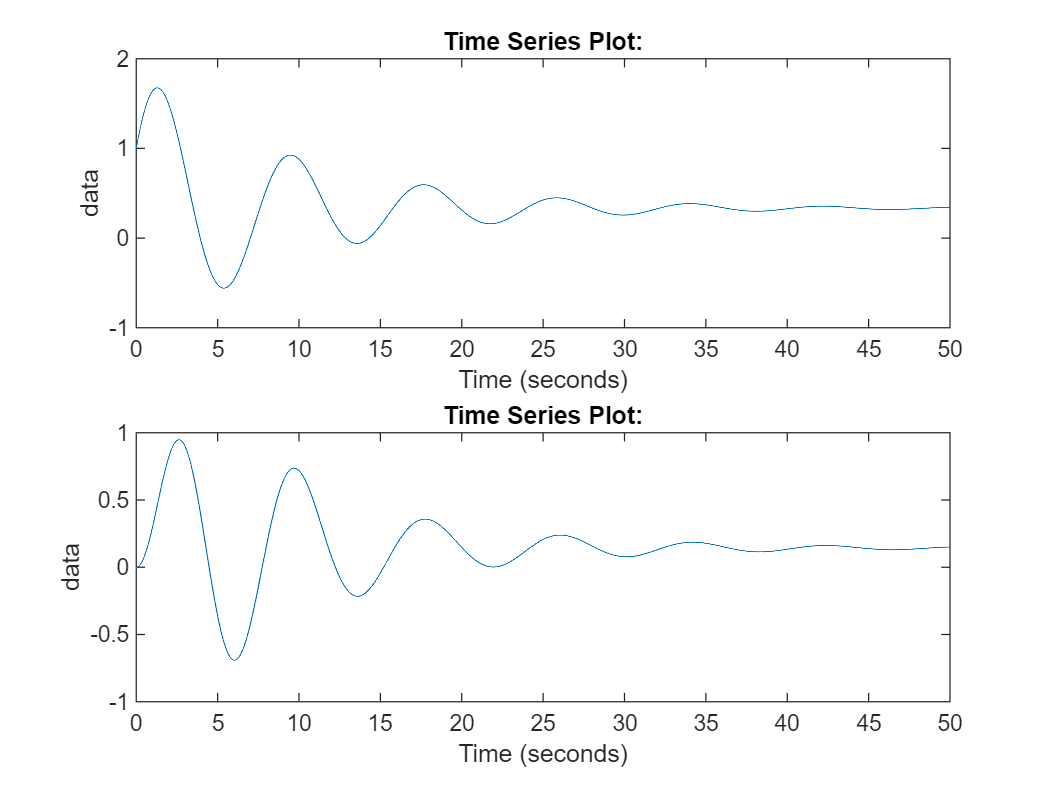

figure(6)
subplot(2,1,1)
plot(out.step1);
subplot(2,1,2)
plot(out.step2);

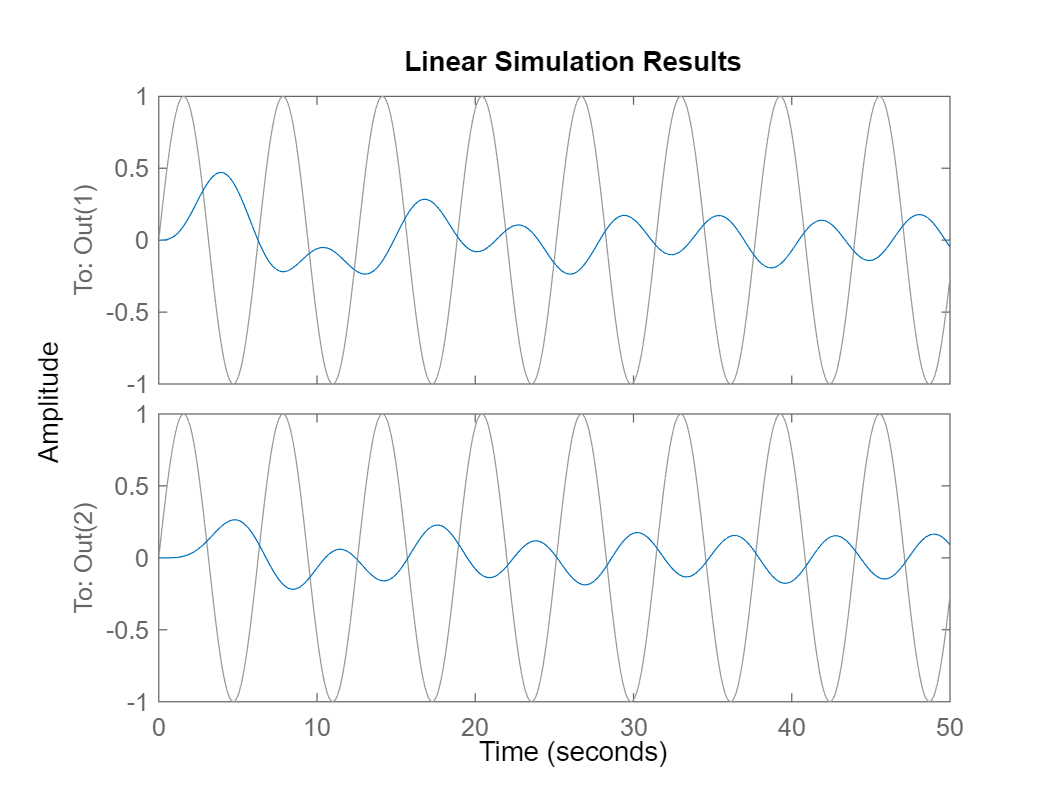

figure(7)
t=0:0.1:50;
y=sin(t);
lsim(T(:,1),y,t);

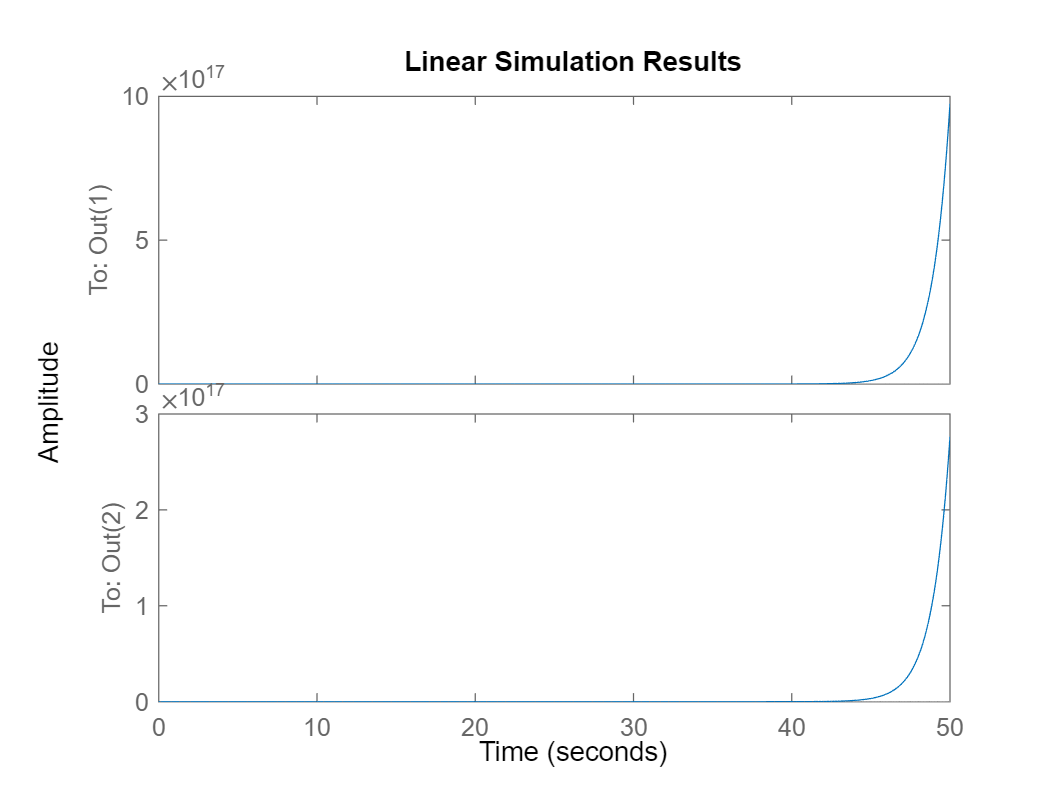

figure(8)
lsim(H(:,1),y,t);

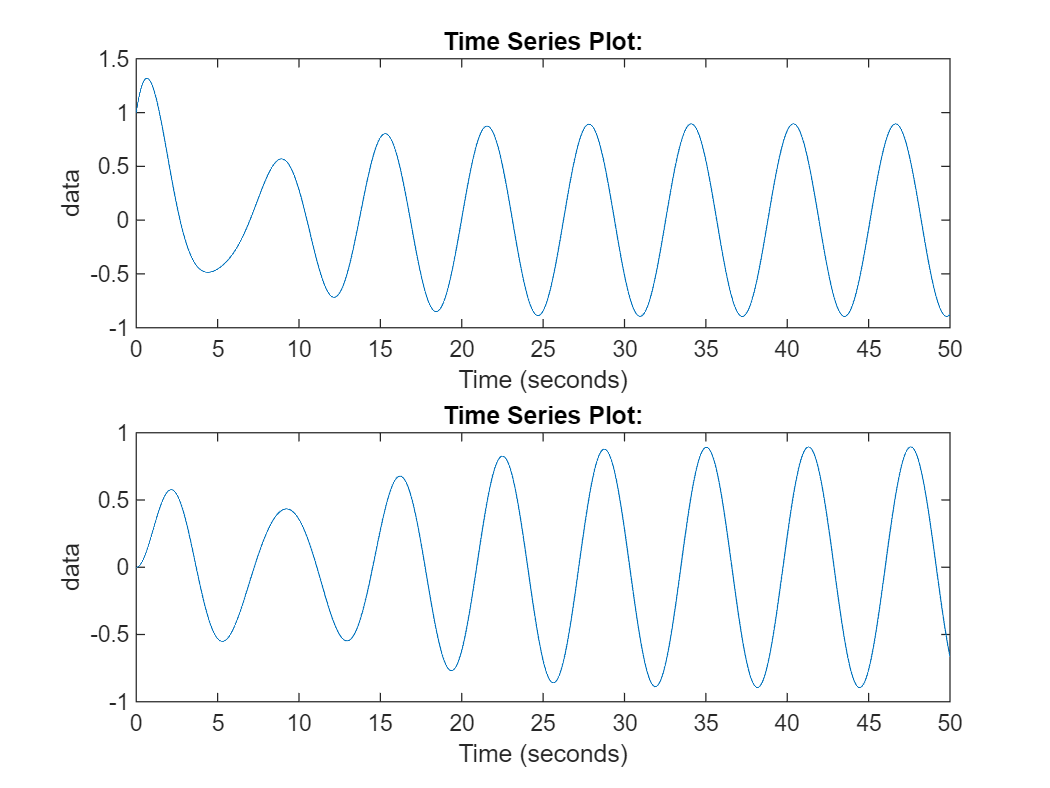

figure(9)
subplot(2,1,1)
plot(out.sin1);
subplot(2,1,2)
plot(out.sin2);

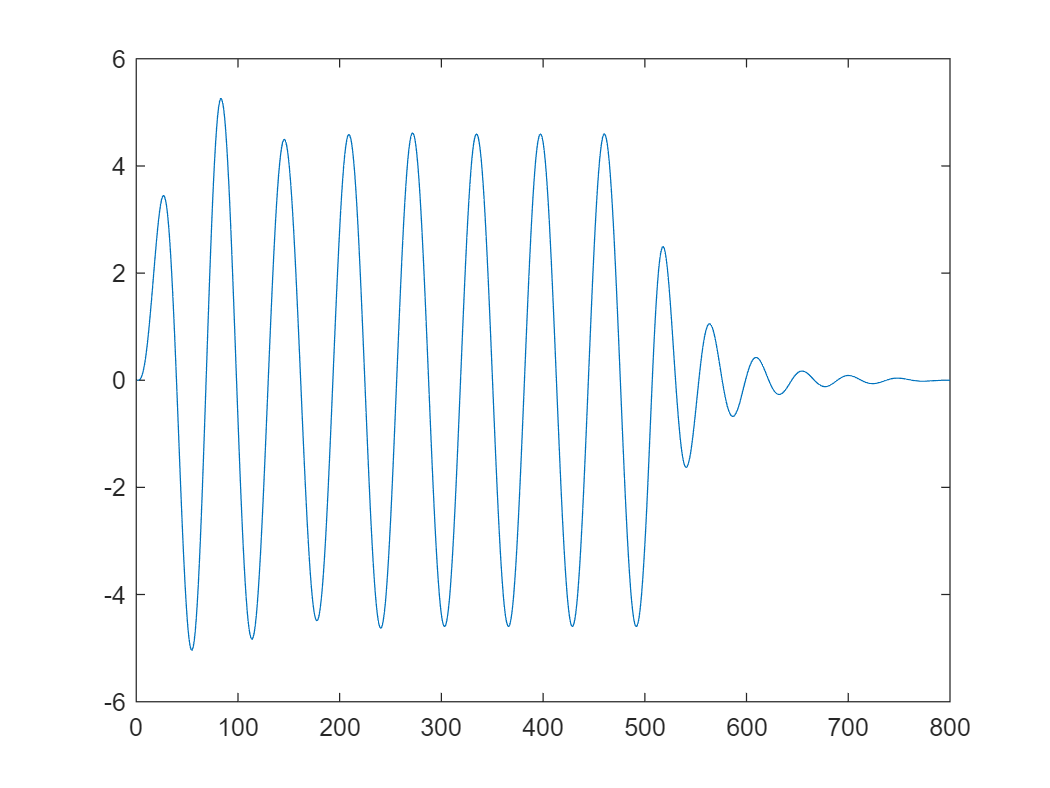

figure(10);
[Y,~] = impulse(T);
x=conv(y,Y(:,1));
 plot(x)

c3=2.5;
k3=5.5;
 %transmitnce
M2=[m1 0;0 m2];
C3=[c1+c2 -c3;-c2 c2+c3];
K2=[k1+k2 -k2;-k2 k2+k3];

%transmittance
s2 = tf('s');
T2 = 1/(M2.*s^2+C3.*s+K2)

T2 =
 
  From input 1 to output...
               0.2 s^2 + 0.15 s + 0.3167
   1:  ------------------------------------------
       s^4 + 1.35 s^3 + 3.267 s^2 + 1.4 s + 1.683
 
                   0.06667 s + 0.1333
   2:  ------------------------------------------
       s^4 + 1.35 s^3 + 3.267 s^2 + 1.4 s + 1.683
 
  From input 2 to output...
                   0.08333 s + 0.1333
   1:  ------------------------------------------
       s^4 + 1.35 s^3 + 3.267 s^2 + 1.4 s + 1.683
 
              0.1667 s^2 + 0.1 s + 0.2333
   2:  ------------------------------------------
       s^4 + 1.35 s^3 + 3.267 s^2 + 1.4 s + 1.683
 
Continuous-time transfer function.



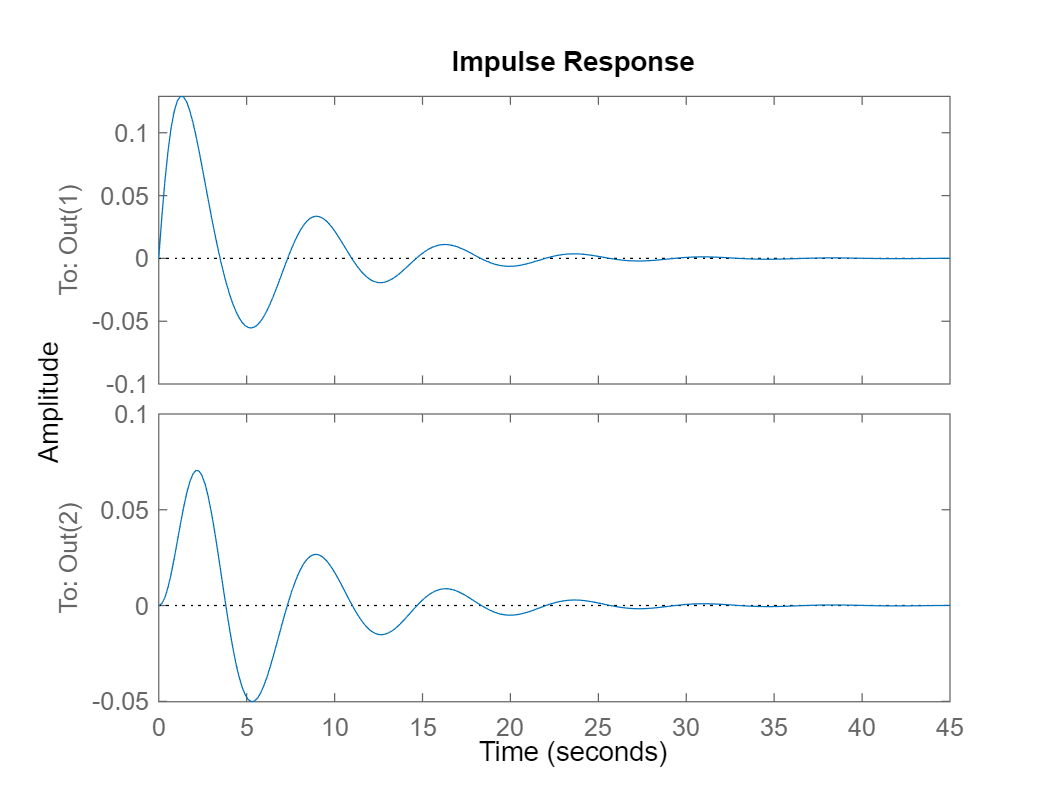


%state
A2=[-(c1+c2)/m1 c2/m1 -(k1+k2)/m1 k2/m1;...
    c2/m2 -(c2+c3)/m2 k2/m2 -(k2+k3)/m2;...
    1 0 0 0;0 1 0 0];
B2=[1/m1;0;0;0];
C4=[0 0 1 0; 0 0 0 1];
D=0;
%state space
sys2 = ss(A2,B2,C4,D);
H2=tf(sys2);
impulse(H2)

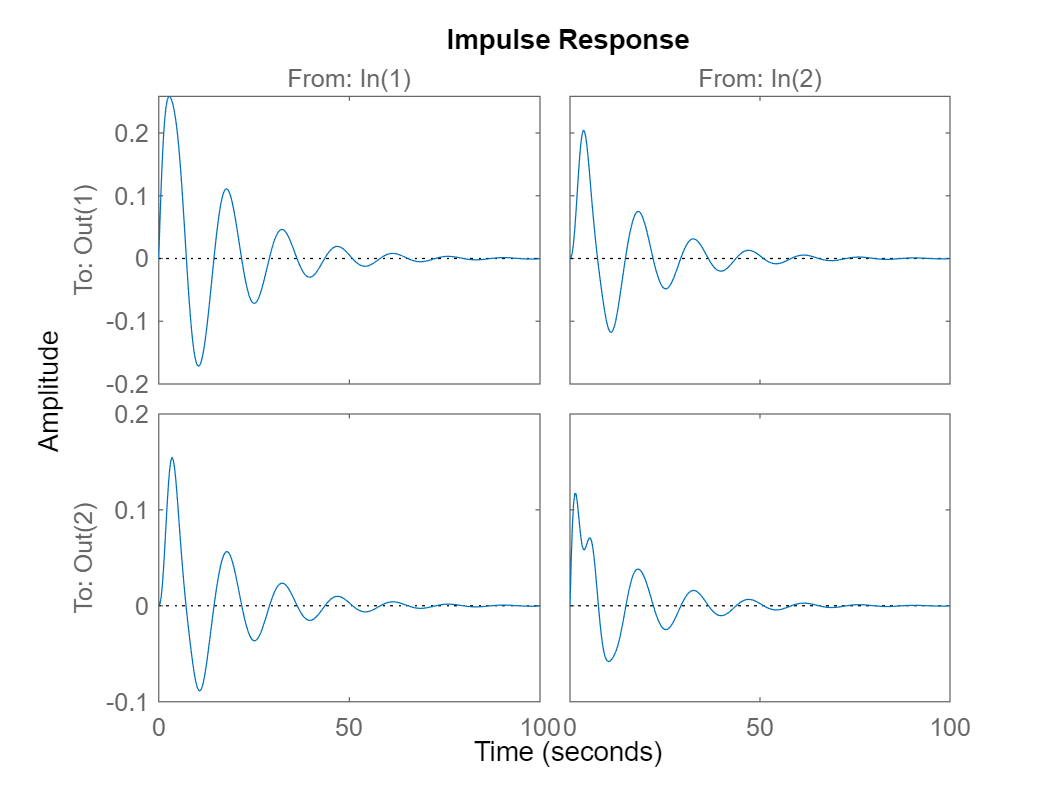

impulse(T)

clear
n=6; %nb of letters in my name
m=n*0.2; %mass
k=n*5; %stiffness
c=n*0.3; %damping ratio
F=5; %input force
%defining state matrices
A = [-c/m -k/m; 1 0];
B = [-1/m 0]';
C = [0 1];
D = 0;
%calculating transfer function
s = tf('s');
sys = 1/(m*s^2+c*s+k)

sys =
 
           1
  --------------------
  1.2 s^2 + 1.8 s + 30
 
Continuous-time transfer function.



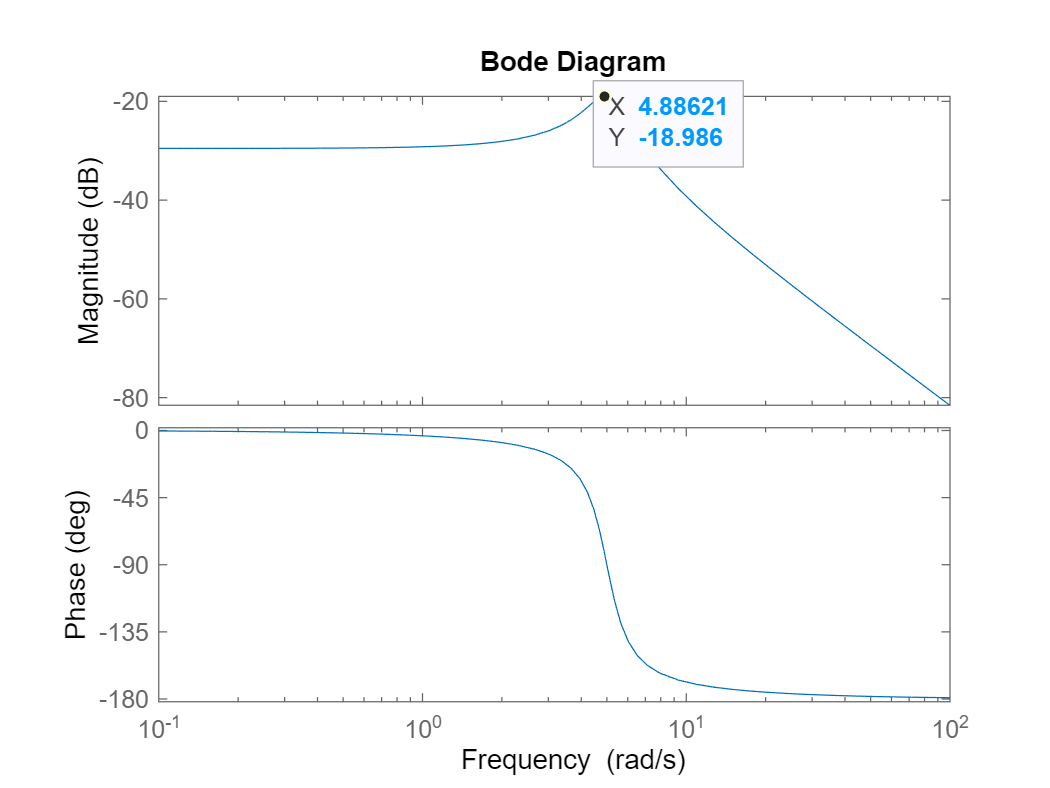

bode(sys.Numerator,sys.Denominator)

clear
n=6;
m=n*0.2;
c=n*0.3;
k=n*5;
s=tf('s');
dampcoeff=(2*sqrt(k*m));
c_un=0;
c_under=dampcoeff/2;
c_crit=dampcoeff;
c_over=dampcoeff*1.5;


%impulse response
figure(1)
hold on
H=1/(m*s^2+c_un*s+k);
impulse(H);
H=1/(m*s^2+c_under*s+k);
impulse(H);
H=1/(m*s^2+c_crit*s+k);
impulse(H);
H=1/(m*s^2+c_over*s+k);
impulse(H);
xlim([0 5])
legend( ...
    'undamped: zeta=0', ...
    'underdamped: zeta<1', ...
    'critically damped: zeta=1', ...
    'overdamped: zeta>1')

%bode plots
figure(2)
hold on
H=1/(m*s^2+c_un*s+k);
bode(H);
H=1/(m*s^2+c_under*s+k);
bode(H);
H=1/(m*s^2+c_crit*s+k);
bode(H);
H=1/(m*s^2+c_over*s+k);
bode(H);
%xlim([0 5])
legend( ...
    'undamped: zeta=0', ...
    'underdamped: zeta<1', ...
    'critically damped: zeta=1', ...
    'overdamped: zeta>1')